clear all
clf

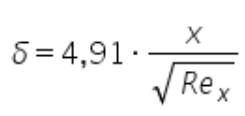

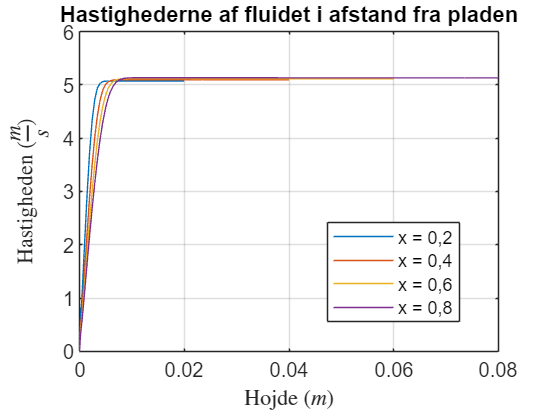

format longg
% Define the filename and sheetname
filename = 'Velocity02.xlsx';
sheetname = 'Plot Data';

% Import data from Excel file
[numericData, textData, rawData] = xlsread(filename, sheetname);

Y = numericData(:,1);
Y1 = Y(1:500);
Y2 = Y(502:1001);
Y3 = Y(1003:1502);
Y4 = Y(1504:2003);
YS = [Y1, Y2, Y3, Y4];

U = numericData(:,2);
U1 = U(1:500);
U2 = U(502:1001);
U3 = U(1003:1502);
U4 = U(1504:2003);
US = [U1, U2, U3, U4];
% Create a new figure
figure;

% Plot 1: Upper left subplot
% subplot(2, 2, 1);
plot(Y1, U1, DisplayName='x = 0,2');
hold on
% title('x=0,2');
% xlabel('Hojde $(m)$',Interpreter='latex')
% ylabel('Hastigheden $(\frac{m}{s})$', Interpreter='latex')
% grid("on")

% Plot 2: Upper right subplot
% subplot(2, 2, 2);
plot(Y2, U2, DisplayName='x = 0,4');
% title('x=0,4');
% xlabel('Hojde $(m)$',Interpreter='latex')
% ylabel('Hastigheden $(\frac{m}{s})$', Interpreter='latex')
% grid("on")

% Plot 3: Lower left subplot
% subplot(2, 2, 3);
plot(Y3, U3, DisplayName='x = 0,6');
% title('x=0,6');
% xlabel('Hojde $(m)$',Interpreter='latex')
% ylabel('Hastigheden $(\frac{m}{s})$', Interpreter='latex')
% grid("on")

% Plot 4: Lower right subplot
% subplot(2, 2, 4);
plot(Y4, U4, DisplayName='x = 0,8');
title('Hastighederne af fluidet i afstand fra pladen');
xlabel('Hojde $(m)$',Interpreter='latex')
ylabel('Hastigheden $(\frac{m}{s})$', Interpreter='latex')
grid("on")
legend('Location', 'best')



x = 0.2:0.2:0.8

x =                        0.2                       0.4                       0.6                       0.8


Re_x = [67257.8894618, 135199.6468247, 203605.5921809, 272375.2291351]

Re_x =              67257.8894618            135199.6468247            203605.5921809            272375.2291351


u_point = [5.070, 5.095, 5.116, 5.133]

u_point =                       5.07                     5.095                     5.116                     5.133


u_point99 = u_point*0.99

u_point99 =                     5.0193                   5.04405                   5.06484                   5.08167



delta_cal = 4.91 * x./sqrt(Re_x)

delta_cal =        0.00378651664466736       0.00534138281592495       0.00652886804974548       0.00752640656968219



deltas_num = [];

% sortere dataen og finder det punkt hvor U_0.99 = 0.99*u
for j = 1:length(u_point)
    for i = 1:length(Y1)
        if u_point99(j)-US(i,j) <= 0
            index = i;
            % disp('next')
            break
        end
    end
    deltas_num(j) = YS(index,j);
end

procent_afvigelse = (delta_cal - deltas_num)./delta_cal * 100

procent_afvigelse =          -2.67419678657542        -0.549645439256935         0.549591101063651        -0.115108990168983


    % Y1_index = find(Y1,u_point99(1)-U1<0)
% Y1(Y1_index)


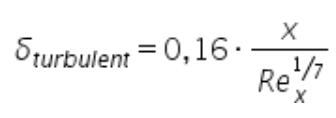

[numericData, textData, rawData] = xlsread('Velocity_turb.xlsx', sheetname);

Y = numericData(:,1);
Y1 = Y(1:500);
Y2 = Y(502:1001);
Y3 = Y(1003:1502);
Y4 = Y(1504:2003);
YS = [Y1, Y2, Y3, Y4];

U = numericData(:,2);
U1 = U(1:500)

U1 =      -8.88178419700125e-16
        0.0801577051759936
         0.160315410351988
         0.240473115527983
         0.320630820703977
         0.400788525879972
         0.480946231055966
         0.561103936231961
         0.641261641407955
         0.721419346583949


U2 = U(502:1001);
U3 = U(1003:1502);
U4 = U(1504:2003);
US = [U1, U2, U3, U4];

Re_x = [998368.5820890, 2002137.8181445, 3016870.5857224, 4041927.9821325]

Re_x =              998368.582089           2002137.8181445           3016870.5857224           4041927.9821325


u_point_turb = [5.007, 5.020, 5.043, 5.067]

u_point_turb =                      5.007                      5.02                     5.043                     5.067


u_point99_turb = u_point*0.99

u_point99_turb =                     5.0193                   5.04405                   5.06484                   5.08167




delta_cal_turb = 0.16 * x./Re_x.^(1/7)

delta_cal_turb =        0.00444742282247222       0.00805316411848058        0.0113925325646666          0.01456839144962



deltas_num_turb = [];

for j = 1:length(u_point)
    for i = 1:length(Y1)
        if u_point99(j)-US(i,j) <= 0
            index = i;
            % disp('next')
            break
        end
    end
    deltas_num_turb(j) = YS(index,j);
end

procent_afvigelse = (delta_cal_turb - deltas_num_turb)./delta_cal_turb * 100

procent_afvigelse =           57.6436149593936          53.2167106653836           50.394676748718          48.2779539090632


New Mesh - Control planes

[numericData, textData, rawData] = xlsread('Vel_control.xlsx', sheetname);

Y = numericData(:,1);
Y1 = Y(1:500);
Y2 = Y(502:1001);
Y3 = Y(1003:1502);
Y4 = Y(1504:2003);
YS = [Y1, Y2, Y3, Y4];

U = numericData(:,2);
U1 = U(1:500)

U1 =                          0
        0.0737016545642695
         0.147403309128539
         0.221104963692808
         0.294806618257078
         0.368508272821347
         0.442209927385617
         0.515911581949886
         0.589613236514156
         0.663314891078425


U2 = U(502:1001);
U3 = U(1003:1502);
U4 = U(1504:2003);
US = [U1, U2, U3, U4];

Re_x = [998368.5820890, 2002137.8181445, 3016870.5857224, 4041927.9821325]

Re_x =              998368.582089           2002137.8181445           3016870.5857224           4041927.9821325


u_point_turb = [5.007, 5.020, 5.043, 5.067]

u_point_turb =                      5.007                      5.02                     5.043                     5.067


u_point99_turb = u_point*0.99

u_point99_turb =                     5.0193                   5.04405                   5.06484                   5.08167




delta_cal_turb = 0.16 * x./Re_x.^(1/7)

delta_cal_turb =        0.00444742282247222       0.00805316411848058        0.0113925325646666          0.01456839144962



deltas_num_turb = [];

for j = 1:length(u_point)
    for i = 1:length(Y1)
        if u_point99(j)-US(i,j) <= 0
            index = i;
            % disp('next')
            break
        end
    end
    deltas_num_turb(j) = YS(index,j);
end

procent_afvigelse = (delta_cal_turb - deltas_num_turb)./delta_cal_turb * 100

procent_afvigelse =           57.6436149593936          53.2167106653836           50.394676748718          48.2779539090632


Fine mesh (x2)

clear all
clf

format longg
% Define the filename and sheetname
filename = 'Velocity02.xlsx';
sheetname = 'Plot Data';

% Import data from Excel file
[numericData, textData, rawData] = xlsread(filename, sheetname);

Y = numericData(:,1);
Y1 = Y(1:500);
Y2 = Y(502:1001);
Y3 = Y(1003:1502);
Y4 = Y(1504:2003);
YS = [Y1, Y2, Y3, Y4];

U = numericData(:,2);
U1 = U(1:500);
U2 = U(502:1001);
U3 = U(1003:1502);
U4 = U(1504:2003);
US = [U1, U2, U3, U4];
% Create a new figure
figure;

% Plot 1: Upper left subplot
% subplot(2, 2, 1);
plot(Y1, U1, DisplayName='x = 0,2');
hold on
% title('x=0,2');
% xlabel('Hojde $(m)$',Interpreter='latex')
% ylabel('Hastigheden $(\frac{m}{s})$', Interpreter='latex')
% grid("on")

% Plot 2: Upper right subplot
% subplot(2, 2, 2);
plot(Y2, U2, DisplayName='x = 0,4');
% title('x=0,4');
% xlabel('Hojde $(m)$',Interpreter='latex')
% ylabel('Hastigheden $(\frac{m}{s})$', Interpreter='latex')
% grid("on")

% Plot 3: Lower left subplot
% subplot(2, 2, 3);
plot(Y3, U3, DisplayName='x = 0,6');
% title('x=0,6');
% xlabel('Hojde $(m)$',Interpreter='latex')
% ylabel('Hastigheden $(\frac{m}{s})$', Interpreter='latex')
% grid("on")

% Plot 4: Lower right subplot
% subplot(2, 2, 4);
plot(Y4, U4, DisplayName='x = 0,8');
title('Hastighederne af fluidet i afstand fra pladen');
xlabel('Hojde $(m)$',Interpreter='latex')
ylabel('Hastigheden $(\frac{m}{s})$', Interpreter='latex')
grid("on")
legend('Location', 'best')



x = 0.2:0.2:0.8

x =                        0.2                       0.4                       0.6                       0.8


Re_x = [67257.8894618, 135199.6468247, 203605.5921809, 272375.2291351]

Re_x =              67257.8894618            135199.6468247            203605.5921809            272375.2291351


u_point = [5.070, 5.095, 5.116, 5.133]

u_point =                       5.07                     5.095                     5.116                     5.133


u_point99 = u_point*0.99

u_point99 =                     5.0193                   5.04405                   5.06484                   5.08167



delta_cal = 4.91 * x./sqrt(Re_x)

delta_cal =        0.00378651664466736       0.00534138281592495       0.00652886804974548       0.00752640656968219



deltas_num = [];

% sortere dataen og finder det punkt hvor U_0.99 = 0.99*u
for j = 1:length(u_point)
    for i = 1:length(Y1)
        if u_point99(j)-US(i,j) <= 0
            index = i;
            % disp('next')
            break
        end
    end
    deltas_num(j) = YS(index,j);
end

procent_afvigelse = (delta_cal - deltas_num)./delta_cal * 100

procent_afvigelse =          -2.67419678657542        -0.549645439256935         0.549591101063651        -0.115108990168983


    % Y1_index = find(Y1,u_point99(1)-U1<0)
% Y1(Y1_index)


[numericData, textData, rawData] = xlsread('Velocity_turb.xlsx', sheetname);

Y = numericData(:,1);
Y1 = Y(1:500);
Y2 = Y(502:1001);
Y3 = Y(1003:1502);
Y4 = Y(1504:2003);
YS = [Y1, Y2, Y3, Y4];

U = numericData(:,2);
U1 = U(1:500)

U1 =      -8.88178419700125e-16
        0.0801577051759936
         0.160315410351988
         0.240473115527983
         0.320630820703977
         0.400788525879972
         0.480946231055966
         0.561103936231961
         0.641261641407955
         0.721419346583949


U2 = U(502:1001);
U3 = U(1003:1502);
U4 = U(1504:2003);
US = [U1, U2, U3, U4];

Re_x = [998368.5820890, 2002137.8181445, 3016870.5857224, 4041927.9821325]

Re_x =              998368.582089           2002137.8181445           3016870.5857224           4041927.9821325


u_point_turb = [5.007, 5.020, 5.043, 5.067]

u_point_turb =                      5.007                      5.02                     5.043                     5.067


u_point99_turb = u_point*0.99

u_point99_turb =                     5.0193                   5.04405                   5.06484                   5.08167




delta_cal_turb = 0.16 * x./Re_x.^(1/7)

delta_cal_turb =        0.00444742282247222       0.00805316411848058        0.0113925325646666          0.01456839144962



deltas_num_turb = [];

for j = 1:length(u_point)
    for i = 1:length(Y1)
        if u_point99(j)-US(i,j) <= 0
            index = i;
            % disp('next')
            break
        end
    end
    deltas_num_turb(j) = YS(index,j);
end

procent_afvigelse = (delta_cal_turb - deltas_num_turb)./delta_cal_turb * 100

procent_afvigelse =           57.6436149593936          53.2167106653836           50.394676748718          48.2779539090632


New Mesh - Control planes

[numericData, textData, rawData] = xlsread('Vel_control_fine.xlsx', sheetname);

Y = numericData(:,1);
Y1 = Y(1:500);
Y2 = Y(502:1001);
Y3 = Y(1003:1502);
Y4 = Y(1504:2003);
YS = [Y1, Y2, Y3, Y4];

U = numericData(:,2);
U1 = U(1:500)

U1 =                          0
          2.24362509593559
          2.89524226251158
          2.96731093394178
          3.05710888002814
           3.1469068261145
          3.23670477220086
          3.32650271828722
          3.40080964646501
          3.45340178509043


U2 = U(502:1001);
U3 = U(1003:1502);
U4 = U(1504:2003);
US = [U1, U2, U3, U4];

Re_x = [998368.5820890, 2002137.8181445, 3016870.5857224, 4041927.9821325]

Re_x =              998368.582089           2002137.8181445           3016870.5857224           4041927.9821325


u_point_turb = [5.007, 5.020, 5.043, 5.067]

u_point_turb =                      5.007                      5.02                     5.043                     5.067


u_point99_turb = u_point*0.99

u_point99_turb =                     5.0193                   5.04405                   5.06484                   5.08167




delta_cal_turb = 0.16 * x./Re_x.^(1/7)

delta_cal_turb =        0.00444742282247222       0.00805316411848058        0.0113925325646666          0.01456839144962



deltas_num_turb = [];

for j = 1:length(u_point)
    for i = 1:length(Y1)
        if u_point99(j)-US(i,j) <= 0
            index = i;
            % disp('next')
            break
        end
    end
    deltas_num_turb(j) = YS(index,j);
end

procent_afvigelse = (delta_cal_turb - deltas_num_turb)./delta_cal_turb * 100

procent_afvigelse =           12.5836308736421          9.41958873510445          8.17738036464798          6.46012941000822


New Mesh extra fine - Control planes

[numericData, textData, rawData] = xlsread('Vel_control_fine2.xlsx', sheetname);

Y = numericData(:,1);
Y1 = Y(1:500);
Y2 = Y(502:1001);
Y3 = Y(1003:1502);
Y4 = Y(1504:2003);
YS = [Y1, Y2, Y3, Y4];

U = numericData(:,2);
U1 = U(1:500)

U1 =                          0
          1.99867222098495
          2.42911402640765
          2.77640319480278
          2.96496458490425
          3.09102763282914
          3.18522226557893
          3.26436836125521
          3.33229739431199
          3.39183348059333


U2 = U(502:1001);
U3 = U(1003:1502);
U4 = U(1504:2003);
US = [U1, U2, U3, U4];

Re_x = [998368.5820890, 2002137.8181445, 3016870.5857224, 4041927.9821325]

Re_x =              998368.582089           2002137.8181445           3016870.5857224           4041927.9821325


u_point_turb = [5.007, 5.020, 5.043, 5.067]

u_point_turb =                      5.007                      5.02                     5.043                     5.067


u_point99_turb = u_point*0.99

u_point99_turb =                     5.0193                   5.04405                   5.06484                   5.08167




delta_cal_turb = 0.16 * x./Re_x.^(1/7)

delta_cal_turb =        0.00444742282247222       0.00805316411848058        0.0113925325646666          0.01456839144962



deltas_num_turb = [];

for j = 1:length(u_point)
    for i = 1:length(Y1)
        if u_point99(j)-US(i,j) <= 0
            index = i;
            % disp('next')
            break
        end
    end
    deltas_num_turb(j) = YS(index,j);
end

procent_afvigelse = (delta_cal_turb - deltas_num_turb)./delta_cal_turb * 100

procent_afvigelse =           3.57163405649164          4.44264306120901          3.95565072624096          5.35966034424336


procent_afvigelse = (deltas_num_turb - delta_cal_turb)./deltas_num_turb * 100

procent_afvigelse =          -3.70392469222598         -4.64918997713042         -4.11856684557882         -5.66318798488944
